% clear all
close all
clc
beep off
% load sim_results_1.mat

### Settings plot style

tratto1=2;
tratto2=2;
tratto3=2;
colore1 = [0.25 0.25 0.25];
colore2 = [0.5 0.5 0.5];
colore3 = [0.75 0.75 0.75];

fontsize_plotting = 11;


### Define limits of the traces

t1c = time_tc_sim(end) - 40e-3;
t2c = time_tc_sim(end);

### Plots

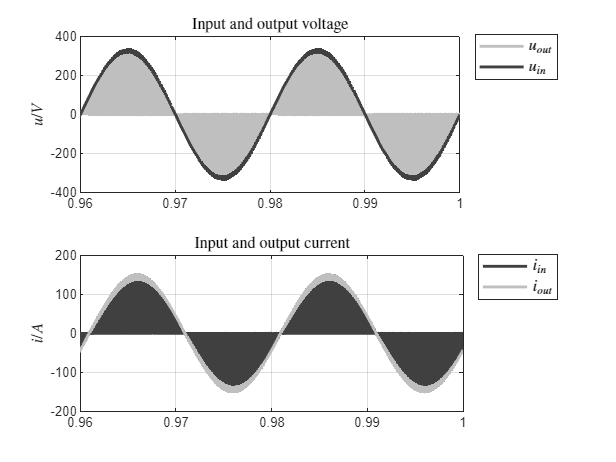

fig1 = figure;
subplot 211
plot(time_tc_sim,u_in_sim,'-','LineWidth',tratto1,'Color',colore1);
hold on
plot(time_tc_sim,u_out_sim,'-','LineWidth',tratto1,'Color',colore3);
hold off
title('Input and output voltage','Interpreter','latex','FontSize',fontsize_plotting);
legend('$u_{in}$','$u_{out}$','Location','northeastoutside',...
    'Interpreter','latex','FontSize',fontsize_plotting);
ylabel('$u/V$','Interpreter','latex','FontSize', fontsize_plotting);
set(gca,'xlim',[t1c t2c]);
grid on
chH = get(gca,'Children');
set(gca,'Children',[chH(2); chH(1)])
subplot 212
plot(time_tc_sim,i_in_sim,'-','LineWidth',tratto1,'Color',colore1);
hold on
plot(time_tc_sim,i_out_sim,'-','LineWidth',tratto1,'Color',colore3);
hold off
title('Input and output current','Interpreter','latex','FontSize',fontsize_plotting);
legend('$i_{in}$','$i_{out}$','Location','northeastoutside',...
    'Interpreter','latex','FontSize',fontsize_plotting);
ylabel('$i/A$','Interpreter','latex','FontSize', fontsize_plotting);
set(gca,'xlim',[t1c t2c]);
grid on
chH = get(gca,'Children');
set(gca,'Children',[chH(1); chH(2);]);
h=gcf;
set(h,'PaperOrientation','landscape');
set(h,'PaperUnits','normalized');
set(h,'PaperPosition', [0 0 1 1]);
% set(fig1,'PaperSize',fliplr(get(fig1,'PaperSize')));
print(fig1,'-depsc','figure_1');